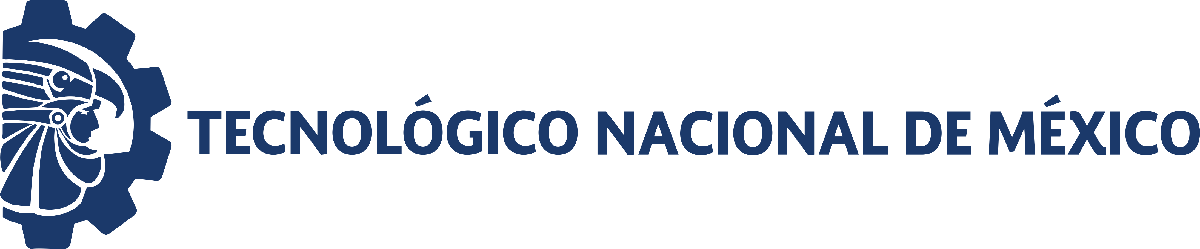                                 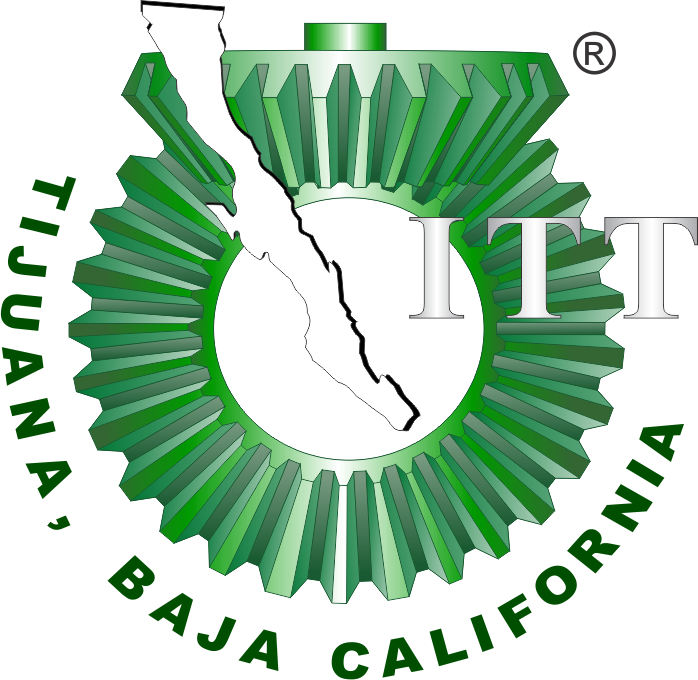

**Departamento de Ingeniería Eléctrica y Electrónica**

**Ingeniería Biomédica**

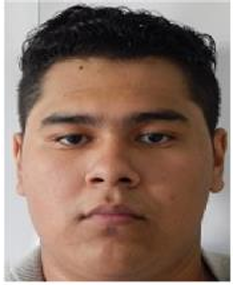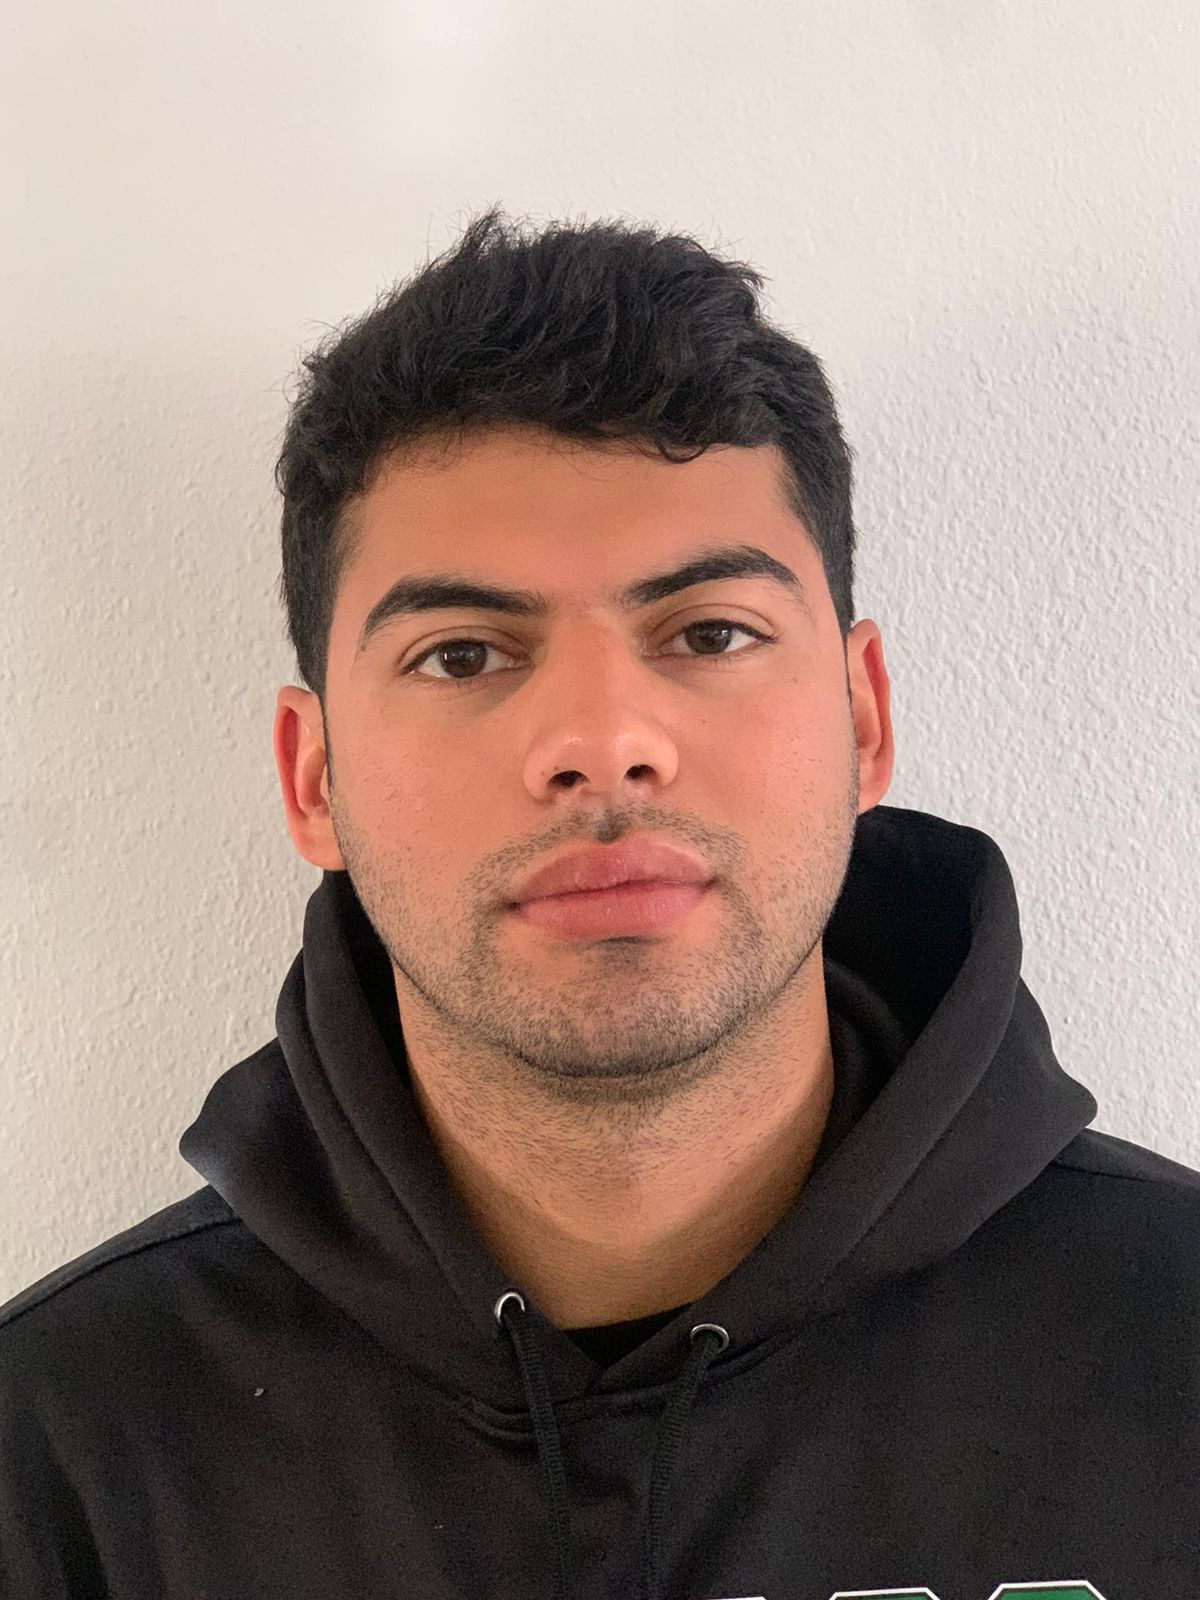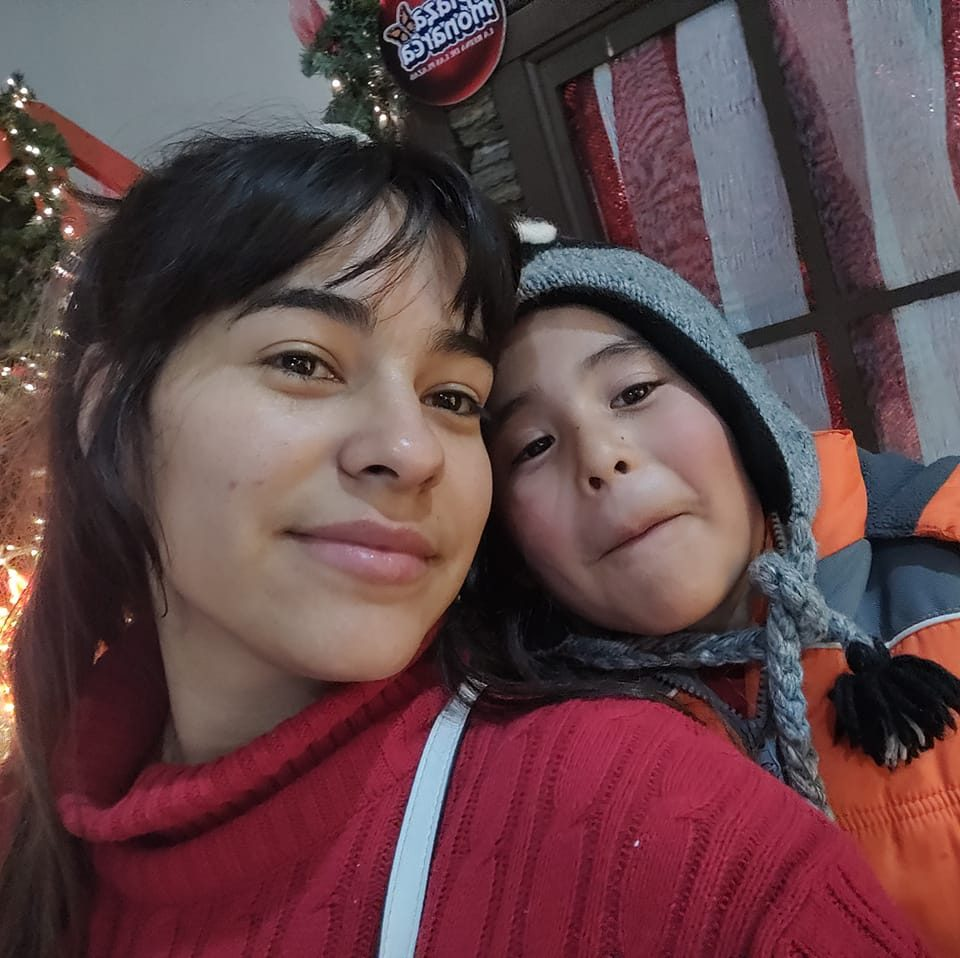

## Datos de los alumnos

Nombre: **Mauricio Jesus Meraz Galeana**

**                Perez Chavez Marco Antonio**

**                Meza Armenta Alejandra Lizette**

Número de control: **18210139**

**                                19212423**

**                                19212415**

Correo institucional: **mauricio.meraz18@tectijuana.edu.mx**

**                                 marco.perez193@tectijuana.edu.mx**

**                                 alejandra.meza193@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Carrera: **Ingeniería Biomédica**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

# Proyecto final: Sistema Urinario con caso de incontinencia

## Datos Generales de la Simulación

% Datos Generales de la Simulación
clc; clear;
close all; 
warning('off','all')

tend = '10';
file = 'ProyectoFinal';
open_system(file);
parameters = struct('StopTime', tend, 'Solver', 'ode15s');

% Ejecuta la simulación
N = sim(file, parameters);

Found algebraic loop that contains: 
ProyectoFinal/Caso/Gain12
ProyectoFinal/Caso/Derivative2
ProyectoFinal/Caso/Gain11
ProyectoFinal/Caso/Gain14
ProyectoFinal/Caso/Add11
ProyectoFinal/Caso/Gain17
ProyectoFinal/Caso/Add9 (algebraic variable)
ProyectoFinal/Caso/Add7 (algebraic variable)


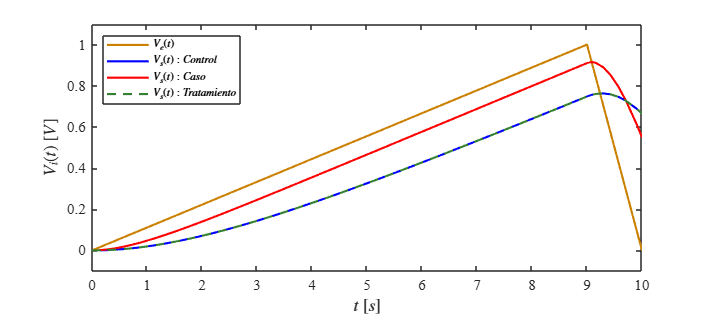

% Extraer los datos y tiempos de las señales si son 'timeseries'
Ve_time = N.Ve.Time; % Tiempo de Ve
Ve_data = N.Ve.Data; % Datos de Ve

Ppx_time = N.Ppx.Time; % Tiempo de Ppx
Ppx_data = N.Ppx.Data; % Datos de Ppx

Ppy_time = N.Ppy.Time; % Tiempo de Ppy
Ppy_data = N.Ppy.Data; % Datos de Ppy

Ppz_time = N.Ppz.Time; % Tiempo de Ppz
Ppz_data = N.Ppz.Data; % Datos de Ppz

% Llama a la función para graficar usando los datos y tiempos
plotsignals(Ve_time, Ve_data, Ppx_time, Ppx_data, Ppy_time, Ppy_data, Ppz_time, Ppz_data);

## Respuesta a las señales

function plotsignals(t1, Ve, t2, Ppx, t3, Ppy, t4, Ppz)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on

    % Plots
    plot(t1, Ve, 'LineWidth', 1.5, 'Color', [0.8, 0.5, 0])
    plot(t2, Ppx, 'LineWidth', 1.5, 'Color', "b")
    plot(t3, Ppy, 'LineWidth', 1.5, 'Color', "r")
    plot(t4, Ppz, '--','LineWidth', 1.5, 'Color', [0.2, 0.5, 0.2])

    % Configuración de ejes
    xlim([min([t1; t2; t3; t4]), max([t1; t2; t3; t4])]) % Adjust x-limits based on data
    ylim([min([Ve; Ppx; Ppy; Ppz])-0.1, max([Ve; Ppx; Ppy; Ppz])+0.1]) % Adjust y-limits with padding
    xlabel('$t$ $[s]$', 'Interpreter', 'latex', 'FontSize', 12)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter', 'latex', 'FontSize', 12)


    % Leyenda
    L = legend('$V_e(t)$', '$V_s(t): Control$', '$V_s(t): Caso$', '$V_s(t): Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 8, 'Location', 'northwest', 'Box', 'On')

    % Exportar la gráfica a un PDF
    name = 'proyectofinal.pdf';
    exportgraphics(gcf, name, 'ContentType', 'vector')
end
